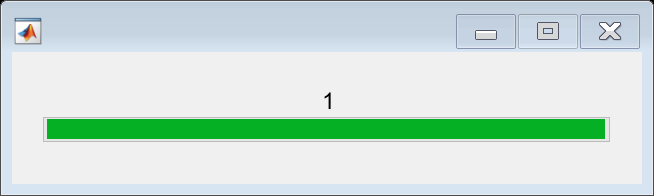

shapes_file = fopen('Chr1shape/chr1_shape_matrices_2nd.txt','rt');

regulatory_regions_file = fopen('RegTfbs/chr1_regTfbs.txt','rt');

thisline_Reg = fgetl(regulatory_regions_file);
thisline = fgetl(shapes_file);

loading = waitbar(0,'Please wait...');

initial2 = repmat([0], 10003896, 88);

for i=1:480
    r = i/480;
    progress = round(r,5);
    waitbar(progress,loading,string(progress));
    thisline_Reg = fgetl(regulatory_regions_file);
    if ~ischar(thisline_Reg); break; end  %end of file
    C = strsplit(thisline_Reg,"\t");
    start = C(1,1);
    stop = C(1,2);
    start = str2double(start{1});
    stop = str2double(stop{1});
    
    if ~ischar(thisline); break; end  %end of file
    C = strsplit(thisline,"\t");
    n1 = C(1,1);
    n1 = str2double(n1{1});

    while n1 < start
        thisline = fgetl(shapes_file);
        
        if ~ischar(thisline); break; end  %end of file
        C = strsplit(thisline,"\t");
        n1 = C(1,1);
        n1 = str2double(n1{1});
    end

    while n1 < stop
        % first shapes
        C = strsplit(thisline,"\t");
        n1 = C(1,1);
        n1 = str2double(n1{1});
        data = C(1,2);  
        data = string(data{1});
        C2 = strsplit(data," ");
        C2 = C2';
        C2(1, :) = [];
        C2 = C2';
        
        C2 = str2double(C2);
        initial2(n1, :) = C2;
        
        thisline = fgetl(shapes_file);
    end
end

initial2(237550, :)

ans =     0.2710    0.3330    0.3454    0.4416    0.5536    0.4670    0.3566    0.3348    0.2379    0.2419    0.3876    0.4963    0.5239    0.4311    0.3373    0.2825    0.2226    0.1428    0.1493    0.2309    0.2841    0.2771    0.1392    0.2923    0.3672    0.1868    0.3563    0.5720    0.3646    0.2625    0.1836    0.1281    0.1224    0.2362    0.5442    0.7311    0.6510    0.2944    0.1053    0.1211    0.4573    0.9619    0.9091    0.8456    0.1182    0.0888    0.1758    0.2411    0.1508    0.2797


save("chr1shapes2", "initial2", '-v7.3')

fclose(shapes_file);
fclose(regulatory_regions_file);


initial2(237550, :)

ans =     4.4600    4.8500    4.8000    4.9200    5.3100    5.4200    4.9400    4.8400    4.8200    4.3000    4.8500    5.1000    5.3800    5.2200    4.9500    4.7300    4.6300    4.3600    4.0500    4.4200    4.6200    4.7500  -10.0800  -10.5900   -3.4600   -9.1200   -9.7100   -2.7400   -5.7000   -7.6500   -8.6500  -10.2200  -10.9100  -10.4800   -6.0800   -2.9200   -2.5600   -4.3900  -10.0900  -11.9300   -9.2100   -0.1400   -1.3200   -1.0300   -2.0000   -4.1900   -3.4300   -0.5900   -1.6900   -3.3800


% save("chr1shapes", "initial")
save("chr1shapes2", "initial2", '-v7.3')


load('chr1shapes2')
initial2(237550, :)

ans =     4.4600    4.8500    4.8000    4.9200    5.3100    5.4200    4.9400    4.8400    4.8200    4.3000    4.8500    5.1000    5.3800    5.2200    4.9500    4.7300    4.6300    4.3600    4.0500    4.4200    4.6200    4.7500  -10.0800  -10.5900   -3.4600   -9.1200   -9.7100   -2.7400   -5.7000   -7.6500   -8.6500  -10.2200  -10.9100  -10.4800   -6.0800   -2.9200   -2.5600   -4.3900  -10.0900  -11.9300   -9.2100   -0.1400   -1.3200   -1.0300   -2.0000   -4.1900   -3.4300   -0.5900   -1.6900   -3.3800
